# **Paradoja del cumpleaños**

Autor: Juan Parras

Asignatura: SALT

## Descripción del problema

El problema consiste en calcular la posibilidad de que en un grupo de $N$ personas, dos cumplan años el mismo día. Para ello, haremos uso de varias de las herramientas que hemos visto en el temario.

## Solución

Es más sencillo calcular primer la probabilidad de que las personas NO cumplan años el mismo día: definimos $\mathrm{NC}$ como el suceso de que las $N$ personas no cumplan años el mismo día, y $C$ la probabilidad de que dos personas (al menos) cumplan años el mismo día. Por tanto, tenemos que:


$$P\left(C\right)=1-P\left(\mathrm{NC}\right)$$


Por simplicidad, comenzamos asumiendo que $N=2$. En este caso, tenemos:


$$P\left(\mathrm{NC}\right)=1\cdot \frac{364}{365}\to P\left(C\right)=1-\frac{364}{365}$$


Donde tenemos que:

- 1 es la probabilidad de que la primera persona cumpla años un día cualquiera del año. Obviamente, esta probabilidad vale siempre 1.

- $\frac{364}{365}$ es la probabilidad de que la segunda persona cumpla años otro día diferente al de la primera. Es importante notar que esta probabilidad se obtiene mediante Laplace: para que la segunda persona no cumpla años cuando el primero, debe cumplir años necesariamente cualquier otro día del año (de ahí el 364).

Esta probabilidad es bastante baja:

prob=1-364/365

prob = 0.0027

La expresión anterior es generalizable a $N$ personas: el procedimiento es el mismo, donde sólo tenemos que tener cuidado con el hecho de que cada nueva persona tiene que cumplir años un día en el que nadie haya cumplido, de ahí que cada vez tengamos menos días "disponibles":


$$P\left(\mathrm{NC}\right)=1\cdot \frac{364}{365}\cdot \frac{363}{365}\cdot \frac{362}{365}\ldotp \ldotp \ldotp \frac{365-\left(N-1\right)}{365}=\frac{365}{365}\cdot \;\frac{364}{365}\cdot \frac{363}{365}\cdot \frac{362}{365}\ldotp \ldotp \ldotp \frac{365-N+1}{365}=\frac{365!}{{365}^N \left(365-N\right)!}$$


Es importante notar que para $N\ge 365,P\left(\mathrm{NC}\right)=0$, ya que es imposible que dos o más personas no coincidan. Por tanto, tenemos que:


$$P\left(C\right)=1-\frac{365!}{{365}^N \left(365-N\right)!}$$


¿Cuánto es esta probabilidad? Como depende de N, hagamos una función para calcularlo. Es importante notar que no podemos usar el factorial, porque con valores de $N$ grandes nos dará error:

N=82

N = 82

prob=calcular_prob(N)

prob = 0.9999

¿Sorpresa? Representemos los resultados para tener una visión gráfica: en el eje horizontal, ponemos los valores de $N$, y en el vertical, la probabilidad de coincidencia:

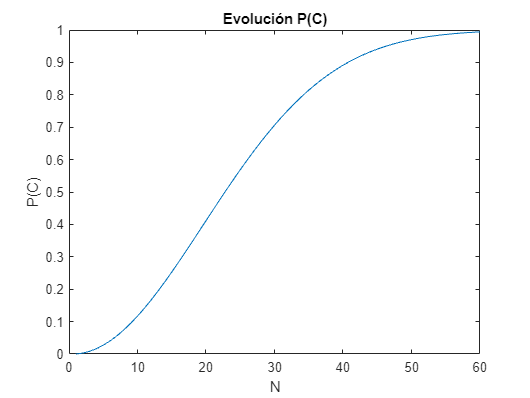

N = 1:60; % Valores de N
valores=[]; % Vector donde vamos a guardar las probabilidades para cada valor de N
for i=1:length(N)
    valores(end+1)=calcular_prob(N(i));
end
plot(N, valores)
title('Evolución P(C)')
ylabel('P(C)')
xlabel('N')

Vemos que con $N=23,\;P\left(C\right)\approx 0\ldotp 5$, y con $N=40,P\left(C\right)\approx 0\ldotp 9$, lo cual puede ser una sorpresa porque con relativamente pocas personas, la probabilidad es muy elevada. Esto se debe a la naturaleza del problema: hay muchas combinaciones posibles de dos personas en un grupo de $N$, y estas combinaciones aumentan de forma factorial con $N$, de ahí que la probabilidad sea sorprendentemente elevada. 

Asimismo, esta probabilidad es sorprendentemente elevada porque es fácil interpretar mal el problema, y pensar que estamos calculando la probabilidad de que haya alguien que cumple años el mismo día que yo. ¡Esto es muy diferente! En este caso, si estamos en un grupo de $N$ personas (contando conmigo), la probabilidad de que alguien no cumpla años cuando yo es:


$$P\left(\mathrm{NC}\right)={\left(\frac{364}{365}\right)}^{N-1}$$


En este caso, nos da igual que dos personas cumplan años en el mismo día, siempre y cuando NO coincida con mi cumpleaños. Por tanto, tenemos que la probabilidad de coincidir es la siguiente:


$$P\left(C\right)=1-{\left(\frac{364}{365}\right)}^{N-1}$$


Donde, ahora, $N\in \left(1,\infty \;\right)$, ya que es posible que varias personas que no coinciden con mi cumpleaños sí concidan entre ellas (estamos en un caso de rango infinito numerable).

En este caso, las probabilidades son mucho más bajas, como cabe esperar:

N=128

N = 128

prob=1-(364/365)^N

prob = 0.2961

En este caso, necesitamos $N\approx 250$ para tener $P\left(C\right)\approx \;0\ldotp 5$. Como vemos en la siguiente figura, esta probabilidad evoluciona mucho más lento que el caso original.

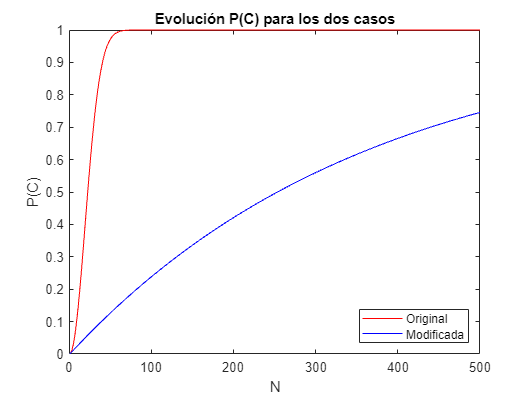

N = 1:500; % Valores de N
valores=[]; % Vector donde vamos a guardar las probabilidades para cada valor de N
for i=1:length(N)
    valores(end+1)=calcular_prob(N(i));
end
plot(N, valores, 'r', N, 1-(364/365).^(N-1), 'b')
title('Evolución P(C) para los dos casos')
xlabel('N')
ylabel('P(C)')
legend({'Original','Modificada'},'Location','southeast')

Por tanto, es importante tener cuidado con cómo entendemos el problema, ya que pequeños detalles pueden tener un gran impacto, como acabamos de ver.

Finalmente, aquí está la función que hemos usado para calcular $P\left(C\right)$ sin emplear factorial (usando un bucle):

function pc = calcular_prob(N)
    if N>0 && N<365  % Calcula sólo si se cumplen las condiciones de rango de N
        pnc = 1;
        for i=1:N  % Usamos un bucle para calcular cada término del producto
            pnc = pnc * (365-i+1)/365;
        end
        pc = 1 - pnc;
    else % En caso de que N >= 365, sabemos que P(C)=1
        pc = 1;
    end
end